clear;
m = 100000;
n = 10000;
density = 1e2/m;
max_iter = 1000;
lda = 0.1;
rho = 0.1;
abs_tolerance = 1e-4;
rel_tolerance = 1e-3;
x = sprand(m, n, density);
theta = rand(n, 1);
noise = -0.5 + rand(m, 1);
y = x*theta + noise;
iters = 1000;
alpha = 0.001;
theta_old = rand(n, 1);

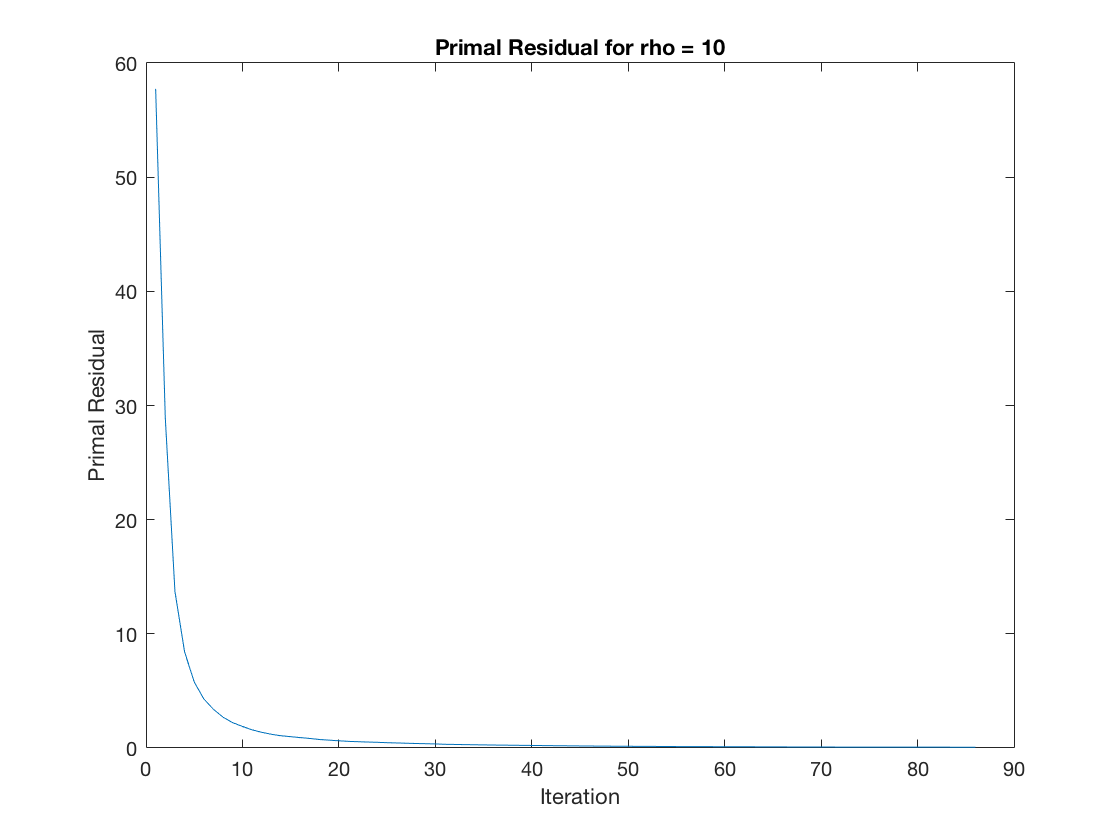


A = x;
b = y;

tic
L = chol(A'*A + rho*speye(n), 'lower');
U = L';
ATb = A'*b;

primal_residuals = [];
dual_residuals = [];
err_lasso = [];
%spy(L)
x_ad = zeros(n, 1);
y_ad = zeros(n, 1);
z = zeros(n, 1);

err_lasso = [err_lasso; (1/(2*m))*sum((A*x_ad - b).^2)];

for i = 1:iters
%    i
    q = ATb + rho*(z - y_ad);
    x_ad = U \ (L \ q);
    z_prev = z;
    xy = x_ad + y_ad;
    z = max(0, xy - lda/rho) - max(0, -xy - lda/rho);
    y_ad = xy - z;
    primal_residual = norm(x_ad - z);
    primal_residuals = [primal_residuals; primal_residual];
    dual_residual = norm(-rho*(z - z_prev));
    dual_residuals = [dual_residuals; dual_residual];
    epi_primal = sqrt(n)*abs_tolerance + rel_tolerance*max(norm(x_ad), norm(-z));
    epi_dual = sqrt(n)*abs_tolerance + rel_tolerance*norm(y_ad);
    err_lasso = [err_lasso; (1/(2*m))*sum((A*x_ad - b).^2)];
    if primal_residual < epi_primal && dual_residual < epi_dual
        break;
    end
end
t_lasso = toc;

figure;
plot(primal_residuals);
hold on;
title('Primal Residual for rho = 10');
ylabel('Primal Residual');
xlabel('Iteration');

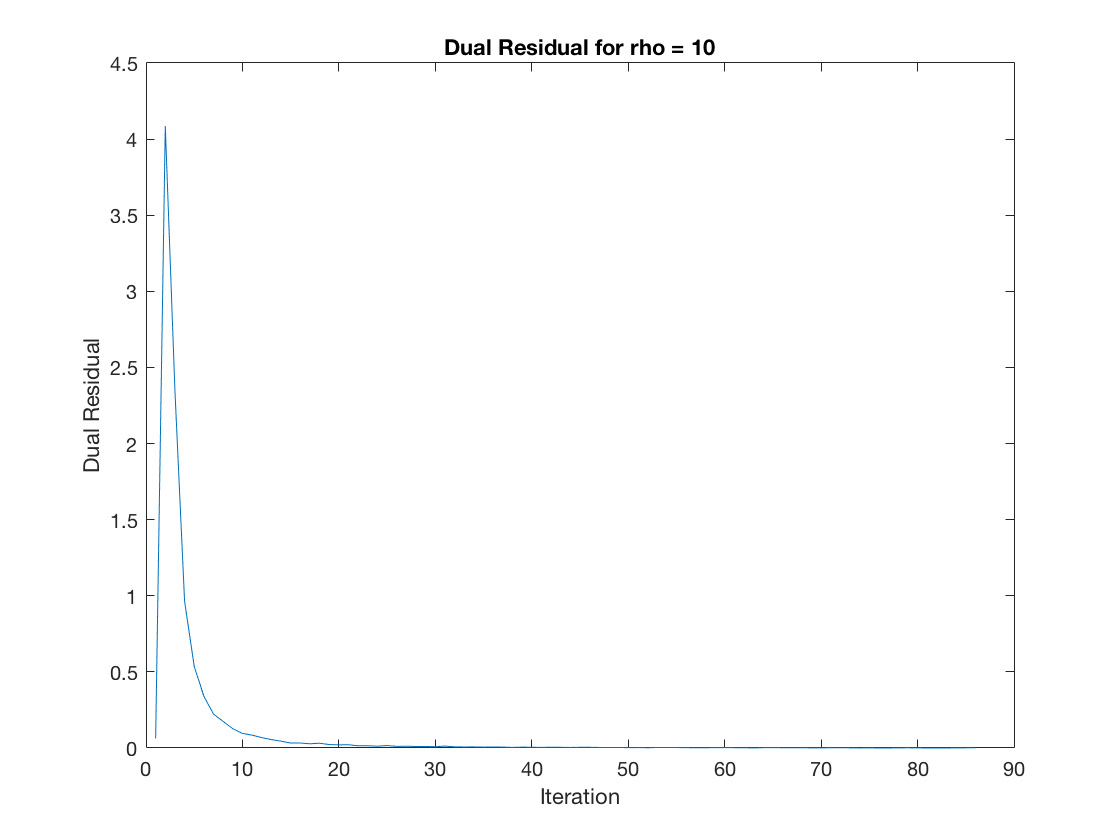


figure;
plot(dual_residuals);
hold on;
title('Dual Residual for rho = 10');
ylabel('Dual Residual');
xlabel('Iteration');

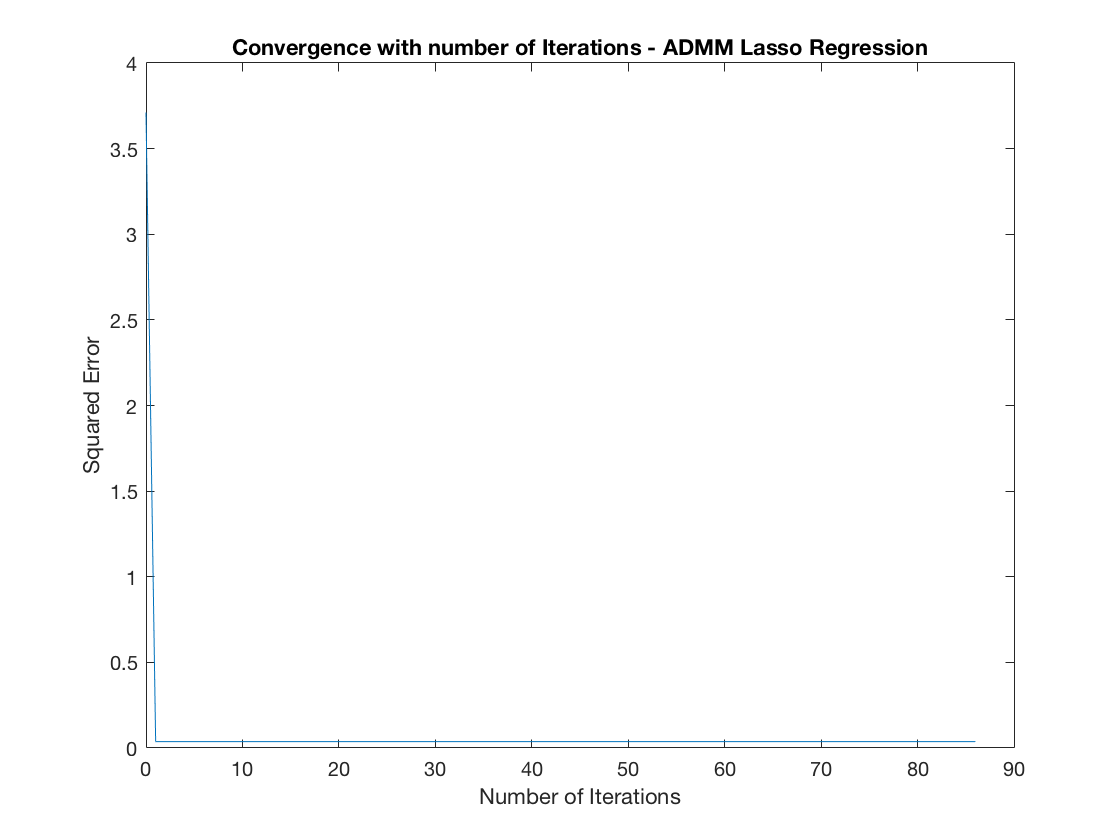


iterations = (0:i)';
figure;
plot(iterations, err_lasso);
hold on;
xlabel('Number of Iterations');
ylabel('Squared Error');
title('Convergence with number of Iterations - ADMM Lasso Regression');

err_lasso(size(err_lasso, 1))

ans = 0.0375

tic
theta_activeset = LassoActiveSet(x, y, 1.5);

      iter            n(w)         n(step)            f(w) opt(wi)  free
         1        0.00e+00        0.00e+00        7.42e+05     0     0
         2        1.50e+00        1.50e+00        7.42e+05  8055     1
         3        1.50e+00        1.43e+00        7.42e+05  9901     2
         4        1.50e+00        9.55e-01        7.42e+05  9983     3
         5        1.50e+00        4.20e-01        7.41e+05  9992     4
         6        1.50e+00        2.62e-01        7.41e+05  9996     5
         7        1.50e+00        2.25e-01        7.41e+05  9998     6
         8        1.50e+00        1.24e-01        7.41e+05 10000     7
All Components satisfy condition
Number of iterations: 8


t_activeset = toc;
err_activeset = (1/(2*m))*sum((y - x*theta_activeset).^2)

err_activeset = 3.7075

tic
theta_blockcoordinate = LassoBlockCoordinate(x, y, 1.5);

 iter         n(step)            f(w)
    1     5.14018e-02     1.50484e+04
    2     6.14585e-02     1.50484e+04
    3     7.77587e-02     1.50483e+04
    4     6.46201e-02     1.50483e+04
    5     5.69460e-02     1.50483e+04
    6     7.84951e-02     1.50483e+04
    7     6.27333e-02     1.50482e+04
    8     6.54373e-02     1.50482e+04
    9     6.80319e-02     1.50482e+04
   10     6.27655e-02     1.50481e+04
   11     6.04175e-02     1.50481e+04
   12     4.97517e-02     1.50481e+04
   13     4.75962e-02     1.50481e+04
Solution Found


t_blockcoordinate = toc;
err_blockcoordinate = (1/(2*m))*sum((y - x*theta_blockcoordinate).^2)

err_blockcoordinate = 0.0379